# **Week1 - Initial Optical Channel**

The code below implements a preliminary model of an optical channel without DSPs and aims to investigate the feasibility of the model and the variation of the bit error rate (BER) with the signal-to-noise ratio (SNR)

## **Transmitter**

The model of the transmitter consists of the following elements:

- A symbol generator which modulates source bits using a chosen modulation format - QPSK or 16-QAM

- A pulse shaper which creates an electrical signal using the generated symbols

- An AWGN adder

- An IQ modulator which modulates the output of a laser according to an electrical signal

### Modulation

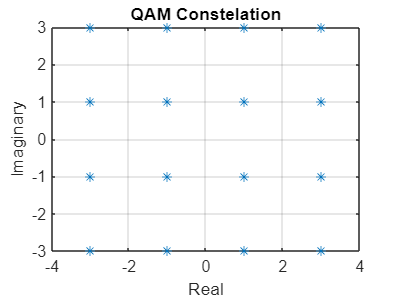

% Modulation parameters
M = 16; % Modulation order
k = log2(M); % Bits per symbol

% Visualising constellation
alphabet = 0:M-1;
symbols = qammod(alphabet, M);
plot(real(symbols), imag(symbols), "*");
title("QAM Constelation");
xlabel("Real");
ylabel("Imaginary");
% xlim([min(real(symbols))-1, max(real(symbols))+1]);
% ylim([min(imag(symbols))-1, max(imag(symbols))+1]);
grid on;

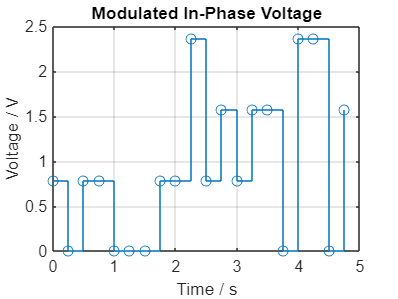


% Generating random bit sequence(s)
NSymb = 20; % No. of symbols
SpS = 1; % Samples per symbol
Rs = 4; % Symbol rate in s
NSequences = 1; % No. of bit sequences

sourceBits = randi([0 1], NSymb*SpS*k, NSequences); % Vector of source bits
sourceInts = bit2int(sourceBits, k); % Vector of source bits converted to ints
modBits = qammod(sourceInts, M); % Maps integer vector to symbol vector

T = 1/(SpS*Rs); % Sampling period in s
t= [0:1:NSymb*SpS - 1]*T; % Time vector for plotting time-series data

% Modulating current with generated symbols
DCOffset = 0; % DC offset of modudlated current in V
Vmax = 1; % Sets the maximum value of the voltage
voltageLevels = [0: pi/k: pi-pi/k]';
realVals = unique(real(symbols))'; % Storing the unique real values in the symbol constellation
imagVals = unique(imag(symbols))'; % Storing the unique imaginary values in the symbol constellation

vI = ones(size(modBits));
vQ = ones(size(modBits));

% Mapping the distinct real & imaginary values to their respective voltage levels
for i=1:k
    vI(real(modBits) == realVals(i)) = Vmax*voltageLevels(i) + DCOffset;
    vQ(imag(modBits) == imagVals(i)) = Vmax*voltageLevels(i) + DCOffset;
end


testVI = zeros(NSymb*SpS, 1); testVQ = testVI; % Test voltages which do not modulate the amplitude

% Visualising in-phase and quadrature currents
stairs(t, vI, "o-");
title("Modulated In-Phase Voltage")
xlabel("Time / s")
ylabel("Voltage / V")
grid on

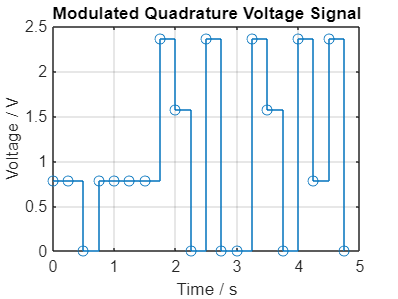


stairs(t, vQ, "o-");
title("Modulated Quadrature Voltage Signal")
xlabel("Time / s")
ylabel("Voltage / V")
grid on

### Pulse Shaping

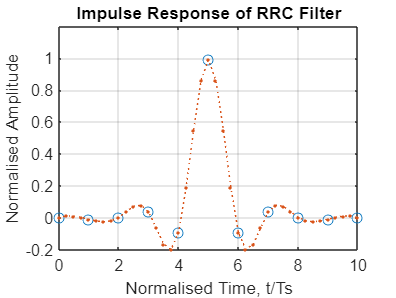

% Graphical output of RRC filter shape
filterResponse = rcosdesign(0.5, 10, 1);
samples = 0:size(filterResponse,2)-1; samples_interp = 0:0.25:size(filterResponse,2)-1;
filterResponse_interp = interp1(samples, filterResponse, samples_interp, "spline");
plot(samples, filterResponse, "o", samples_interp, filterResponse_interp, ":.");
title('Impulse Response of RRC Filter');
xlabel('Normalised Time, t/Ts');
ylabel('Normalised Amplitude');
ylim([-0.2, 1.2]);
grid on

### IQ Modulation

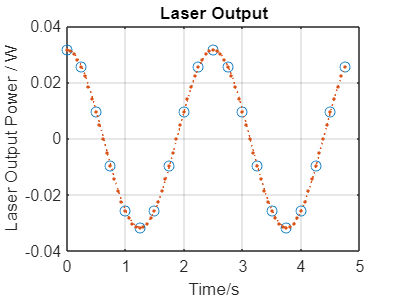

% Initialising laser parameters
centreLambda = 299792458*2.5;
lineWidth = 0;
laserPw_dBm = 0;

% Generating output from laser
laserE = LaserModified(laserPw_dBm, centreLambda, lineWidth, SpS, Rs, NSymb, 1);

% Visualising output from laser
t_interp = [0:0.25:NSymb*SpS - 1]*T;
E_interp = interp1(t, real(laserE), t_interp, "spline");
plot(t, real(laserE), "o", t_interp, E_interp,":.");
title("Laser Output")
xlabel("Time/s")
ylabel("Laser Output Power / W")
grid on

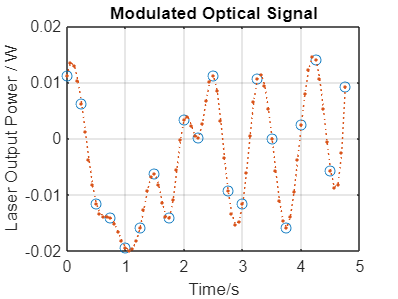


% Modulating optical signal using IQM
Vpi = pi/2; % Voltge required to change phase of E-field by pi
modOpticSig = IQModulatorModified(vI, vQ, laserE, Vpi);

% Visualising modulated optic signal
modOpticSig_interp = interp1(t, real(modOpticSig), t_interp, "spline");
plot(t, real(modOpticSig), "o", t_interp, modOpticSig_interp,":.");
title("Modulated Optical Signal")
xlabel("Time/s")
ylabel("Laser Output Power / W")
grid on

## Optical Channel

### Adding AWGN

### Adding CD

channelOut = modOpticSig;

## Receiver

### Optical Front-End

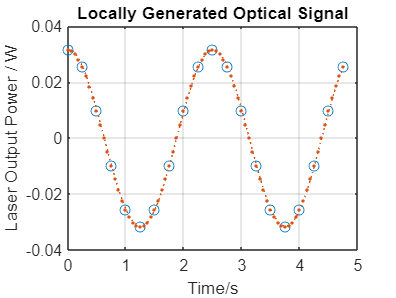

% Generating Local optical signal for coherent detection
Elo = LaserModified(0, centreLambda, 0, SpS, Rs, NSymb, 1); 

% Visualising locally generated optical signal
Elo_interp = interp1(t, real(Elo), t_interp, "spline");
plot(t, real(Elo), "o", t_interp, Elo_interp,":.");
title("Locally Generated Optical Signal")
xlabel("Time/s")
ylabel("Laser Output Power / W")
grid on

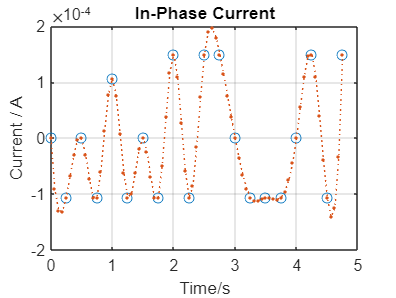


% Generating output from optical front-end
eta_ph = 0.3; % Responsivity of photodetectors
OpticFEOut = OpticalFrontEnd(channelOut, Elo, eta_ph, 1); % Output from optical front-end

% Visualising output from optical front-end
currI_interp = interp1(t, OpticFEOut(:,1), t_interp, "spline");
currQ_interp = interp1(t, OpticFEOut(:,2), t_interp, "spline");

plot(t, OpticFEOut(:,1), "o", t_interp, currI_interp ,":."); % In-phase current
title("In-Phase Current")
xlabel("Time/s")
ylabel("Current / A")
grid on

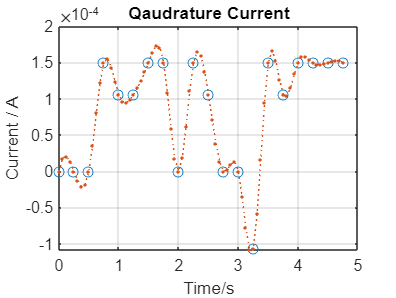


plot(t, OpticFEOut(:,2), "o", t_interp, currQ_interp ,":."); % Qudarature current
title("Qaudrature Current")
xlabel("Time/s")
ylabel("Current / A")
grid on


% TIA amplification and sampling using ADC
TIA_Gain = 1; % TIA amplification factor
Fs = SpS; % Sampling frequency of ADC

sampledFEOut_I = TIA_Gain*OpticFEOut(1:SpS:end, 1);
sampledFEOut_Q = TIA_Gain*OpticFEOut(1:SpS:end, 2);

### Decision

% Scaling factor between output of IQM and output of optical front-end
scaleFactor = TIA_Gain*eta_ph*(1e-3*10^(laserPw_dBm/10))/2;

% Cancelling the scaling factor
scaledVoltageI = sampledFEOut_I/scaleFactor;
scaledVoltageQ = sampledFEOut_Q/scaleFactor;

decodedSymbolsI = ones(size(scaledVoltageI));
decodedSymbolsQ = ones(size(scaledVoltageQ));

% Mapping scaled voltages to inital in-phase and quadrature components of
% the symbol constellation
for i=1:k
    decodedSymbolsI(abs(scaledVoltageI - cos(voltageLevels(i))) < 1e-14) = realVals(i);
    decodedSymbolsQ(abs(scaledVoltageQ -cos(voltageLevels(i))) < 1e-14) = imagVals(i);
end

decodedSymbols = decodedSymbolsI + 1i*decodedSymbolsQ;
decodedInts = qamdemod(decodedSymbols, M);
decodedBits = int2bit(decodedInts, k);

[numErrors, BER] = biterr(sourceBits, decodedBits)

numErrors = 0

BER = 0